% 数据读取（此文件用于生成分解后连杆）
clear; clc; close all force; 
Para_path = '.';
load(fullfile(Para_path, "Data_Dongjili_5tihuan_750s.mat"))

Tswitch = 10;   % 滞留时间
endtime = 10+750;
Ts = 0.001;
data.t = Data(Tswitch/Ts+1:endtime/Ts,1)-Tswitch';
data.q = Data(Tswitch/Ts+1:endtime/Ts,2:4);
data.Pa = Data(Tswitch/Ts+1:endtime/Ts,[5 6 7])*10^6;
data.Pb = Data(Tswitch/Ts+1:endtime/Ts,[8 9 10])*10^6;

clear Data;

% 部分参数定义
dof = 3; 
% 缸内参数，有无杆腔面积
Pam.Aa = [0.063 0.063 0.045].^2.*pi/4;
Pam.Ab(1,1) = (0.063^2-0.035^2)*pi/4;
Pam.Ab(1,2) = (0.063^2-0.035^2)*pi/4;
Pam.Ab(1,3) = (0.045^2-0.030^2)*pi/4;

% 数据预处理
maxNumCompThreads(20);  % 强制设置为20线程
% 向量化计算输出力（避免循环）
data.F = data.Pa .* Pam.Aa - data.Pb .* Pam.Ab;

clear Data;
maxNumCompThreads(20);  % 强制设置为20线程
smoothing_param = 0.9;   % 使用csaps进行平滑样条拟合
for i = 1:3
    fitresult_q(:,i) = csaps(data.t, data.q(:,i), smoothing_param);
    fitresult_F(:,i) = csaps(data.t, data.F(:,i), smoothing_param);
    % 向量化评估（避免循环，速度更快）
    data.qf(:,i) = fnval(fitresult_q(:,i), data.t)';
    data.Ff(:,i) = fnval(fitresult_F(:,i), data.t)';
end

sacle = 100;
fieldNames = fieldnames(data);  % 获取data的所有字段名
for i = 1:length(fieldNames)
    fName = fieldNames{i};
    % 截取前n行，保留所有列
    data.(fName) = downsample(data.(fName),sacle);
end

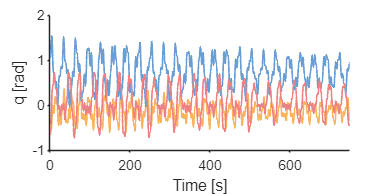

figure;
plot(data.t, data.qf(:,1),'LineWidth',1,'color','#FBB45D')
hold on 
plot(data.t, data.qf(:,2),'LineWidth',1,'color','#699ED4')
plot(data.t, data.qf(:,3),'LineWidth',1,'color','#EF8183')

set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim',[0, 750]);
set(gcf,'unit','centimeters','position',[0 0 10 5]);
xlabel('Time [s]');ylabel('q [rad]');
drawnow update;shg;
hold off

% figure;
% plot(data.t, data.ddq(:,1),'LineWidth',1,'color','#a5cbe0')
% hold on 
% plot(data.t, data.ddq(:,2),'LineWidth',1,'color','#919392')
% plot(data.t, data.ddq(:,3),'LineWidth',1,'color','#015d82')
% 
% set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim',[0, 250]);
% set(gcf,'unit','centimeters','position',[0 0 5 2.5]);
% xlabel('Time [s]');ylabel('q [rad]');
% drawnow update;shg;
% hold off

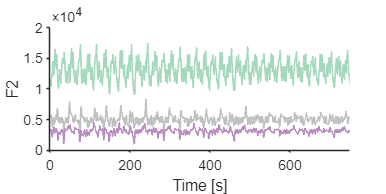

figure;
plot(data.t, data.Ff(:,1),'LineWidth',1,'color','#a4d9bb')
hold on 
plot(data.t, data.Ff(:,2),'LineWidth',1,'color','#bfc0c2')

plot(data.t, data.Ff(:,3),'LineWidth',1,'color','#b88cc0')

set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim',[0, 750]);
set(gcf,'unit','centimeters','position',[0 0 10 5]);
xlabel('Time [s]');ylabel('F2');
drawnow update;shg;
hold off